microphone = ...
    phased.OmnidirectionalMicrophoneElement('FrequencyRange',[20 4000]);
Nele = 11;
ula = phased.ULA(Nele,0.05,'Element',microphone);
c = 340;  % speed of sound, in m/s
fs = 8000;

ang_dft = [15; 0];
collector = phased.WidebandCollector('Sensor',ula,'PropagationSpeed',c, ...
    'SampleRate',fs,'NumSubbands',1000,'ModulatedInput', false);

t_duration = 3;  % 3 seconds
t = 0:1/fs:t_duration-1/fs;
prevS = rng(2008);
noisePwr = 1e-4; 

NSampPerFrame = 1000;
NTSample = t_duration*fs;
sigArray = zeros(NTSample,Nele);
voice_dft = zeros(NTSample,1);

% set up audio device writer
player = audioDeviceWriter('SampleRate',fs);
dftFileReader = dsp.AudioFileReader('SpeechDFT-16-8-mono-5secs.wav', ...
    'SamplesPerFrame',NSampPerFrame);

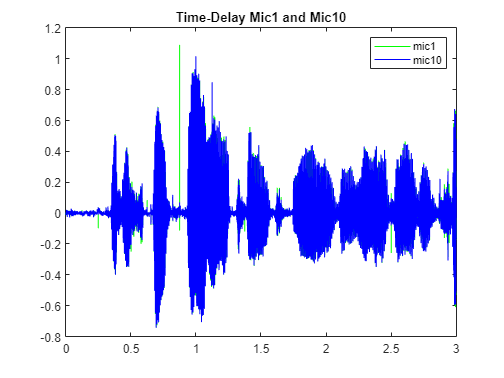

%simulate


for m = 1:NSampPerFrame:NTSample
    sig_idx = m:m+NSampPerFrame-1;
    x1 = dftFileReader();
%     x2 = speechFileReader();
%     x3 = 2*laughterFileReader();
    temp = collector(x1 , ...
        ang_dft );
    player(0.5*temp(:,3));

    
    sigArray(sig_idx,:) = temp;
    voice_dft(sig_idx) = x1;

end
plot(t, sigArray(:,1), "g", t, sigArray(:,10), "b")
legend("mic1", "mic10");
title("Time-Delay Mic1 and Mic10")

Matlab Beamforming

matlabBeamformer = phased.TimeDelayBeamformer('SensorArray',ula, ...
    'SampleRate',fs,'PropagationSpeed',c, "WeightsOutputPort", true,"DirectionSource", "Input port");

%Test for Single Direction
testAngle = [8;0];
[Sum,w] = matlabBeamformer(sigArray, testAngle);
maxAmplitude = sum(abs(Sum).^2)

maxAmplitude = 550.2820

Custom Beamforming

% Gewichtung w kann einzelnen Micros mehr Gewichtung geben
Sum_custom= core.steeredDelayAndSum(sigArray, ula, testAngle, fs,w);

% see core.steeredDelayAndSumLoop for explanation
maxAmplitude = (max(Sum_custom))

maxAmplitude = 1.0044

maxAmplitude = sum(abs(Sum_custom).^2)

maxAmplitude = 550.2820

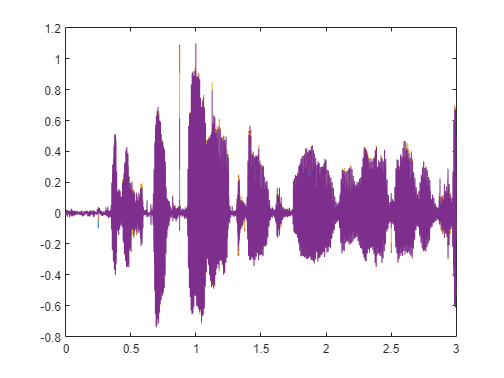

plot(t, sigArray)

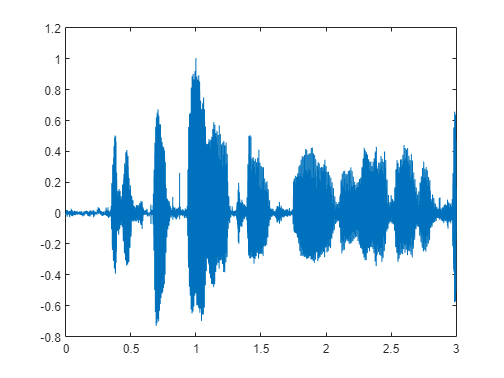

plot(t, Sum_custom)

Beam Scan horizontal Area

tic
w

w =     0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909


scanAngles = -90:1:90;
maxResponses = [];
for angle = scanAngles
    maxResponses(end+1) = sum(abs(core.steeredDelayAndSum(sigArray, ula, [angle; 0], fs, w)).^2);
end
[~, index] = max(maxResponses);
doa = [scanAngles(index); 0]

doa =     15
     0


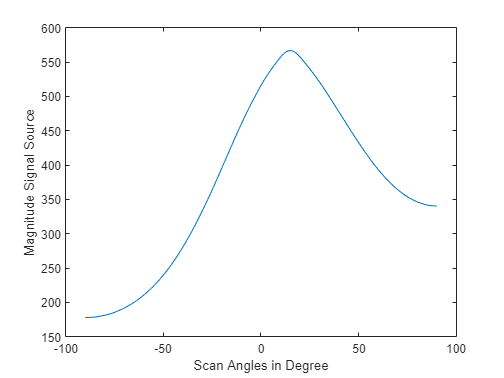

plot(scanAngles, maxResponses)
xlabel("Scan Angles in Degree")
ylabel("Magnitude Signal Source")


% dezibel zu Hörschwelle als Referenz intensitaet = log10(Ausgabe/2*10^-5)
% kamera über .NET dll ansprechen